# Scripts used to generate paper figures

## Fig 1B : Comparing generated and delivered stimulus

### 21.07.2022 M1 N3 used

miscFuncList = miscFuncs;

gen_stim = stim.data.load;
gen_stim_1 = -gen_stim(:,1);


hes_stim_norm = miscFuncList.minmaxNorm(P(1).antennal_movement(1,:));
gen_stim_norm = miscFuncList.minmaxNorm(gen_stim_1');

figure;
plot(time(1:single_trial_length), gen_stim_norm); hold on;
plot(time(1:single_trial_length), hes_stim_norm);
xlim([2 14]);
box off;
ax = gca;
ax.YAxis.Visible = 'off';



## Fig 1C : Basic data processing

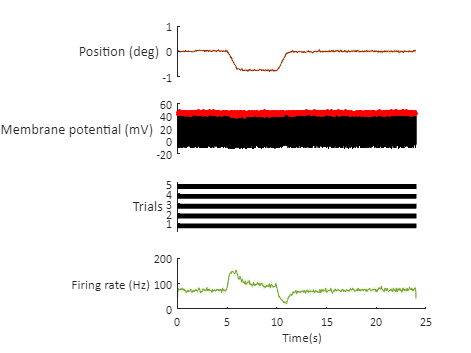

i=1 ;

tickLabelSize = 10;
labelFontSize = 12;
A4 = subplot(4,1,1); 
sdfill(P(i).time(1:P(i).single_trial_length), -P(i).mean_movement, std(-P(i).antennal_movement,[],1), [0.6, 0.2,0])
A4.Box = 'off';
A4.XAxis.Visible = 'off';
A4.FontSize = tickLabelSize;
A4.LineWidth =1;
ylabel('Position (deg)','FontSize', labelFontSize, 'Rotation', 0);
ylim([-1 1]);
A4.FontName = 'Calibri';

[p,l] = findpeaks(P(i).rec(1,:), "MinPeakHeight",0.25*max(P(i).rec(1,:)));
A1 = subplot(4,1,2);
plot(P(i).time(1:P(i).single_trial_length), P(i).rec(1, :),'LineWidth', 0.5, 'Color', 'k'); %#0072BD');
hold on; plot((l/P(i).fs), p, '.', 'MarkerEdgeColor', 'r', 'MarkerSize', 8); %'#A2142F');
hold off;
ylim([-20 60]);
A1.Box = 'off';
A1.XAxis.Visible = 'off';
A1.FontSize = tickLabelSize;
A1.LineWidth = 1;
ylabel('Membrane potential (mV)','FontSize', labelFontSize, 'Rotation', 0);
A1.FontName = 'Calibri';

A2 = subplot(4,1,3);
k = 0.5;
for j = 1:P(i).complete_trials
    l = find(P(i).raster(j,:)==1);
    spike_time = l/P(i).fs;
    for m = 1:length(spike_time)
        line([spike_time(m) spike_time(m)], [k k+0.5], 'Color', 'k', 'LineWidth', 1);
    end
    k = k+1;
end
A2.FontSize = tickLabelSize;
A2.LineWidth =1;
A2.YLimitMethod = 'padded';
ylabel('Trials', 'FontSize', labelFontSize, 'Rotation', 0);
A2.Box = 'off';
A2.XAxis.Visible = 'off';
A2.FontName = 'Calibri';
%


A3 = subplot(4,1,4); 
sdfill(P(i).time(1:P(i).single_trial_length), mean(P(i).gcfr,1), std(P(i).gcfr,[],1), [0.4660 0.6740 0.1880])
ylabel('Firing rate (Hz)','FontSize', labelFontSize, 'Rotation', 0);
xlabel('Time(s)','FontSize', labelFontSize);
ylim([0 200])
A3.Box = 'off';
A3.XAxis.Visible = 'on';
A3.FontSize = tickLabelSize;
A3.LineWidth =1;
A3.FontName = 'Calibri';



% A5 = subplot(3,1,2);
% velocity = diff(-P(i).mean_movement)*fs;
% vel_filtered = filtfilt(b,a,velocity);
% plot(time(2:single_trial_length),vel_filtered, 'LineWidth',2,'Color', [0.8824 0.6314 0], 'LineStyle',':');
% ylabel('Velocity (deg/s)', 'FontSize', labelFontSize, 'Rotation', 0);
% ylim([-2 2])
% A5.LineWidth =1;
% A5.FontSize = tickLabelSize;
% A5.Box = 'off';
% A5.XAxis.Visible = 'off';
% % A5.XLimitMethod = 'padded';
% % A5.YLimitMethod = 'padded';
% A5.FontName = 'Calibri';
% if (P(i).stim_name == "sin" || P(i).stim_name == "sqr" || P(i).stim_name == "sum_sine")
%     title((join(split(P(i).stim_name,"_")," ")) +" Hz");
% else
%     title((join(split(P(i).stim_name,"_"))));
% end

linkaxes([A1,A2,A3,A4], 'x');

%         linkaxes([A1,A2,A4], 'x');
% linkaxes([A3,A4,A5], 'x');






